When we include an interaction term, the interpretation of the simple (marginal) effects of each variable (or main effects of each factor) change, and becomes dependent on the location (centering) of the variables.  The interpretation of a simple effect of x1 below (i.e., b1) in the presence of an interaction is the effect of x1 when x2 is zero. This is also true for x2.  b2 estimates the effect of x2 when x1 is zero.  

If you mean-center x1 and x2, the interpretation of the simple effect of x1 (b1) is the marginal effect of x1 at the average value of x2, and vice versa.

See McClelland, Judd, and Ryan, Data Analysis: A Model Comparison Approach, p. 137, and p. 145.

When you add a product (interaction) term, the slopes for predictors x1 and x2 (b1 and b2) estimate fundamentally different quantities. Instead of testing the average relationship between x1 and the outcome (y), they test the relationship when the other term in the product is zero. 

The interaction term (b3) is invariant with respect to transformations of location and scale, as long as the components (x1 and x2) are included in the model. 

 main (simple) effects 

% Generate variables
x1 = 3 + randn(100, 1); x2 = 3 + randn(100, 1); 
% Generate design matrix (X) - omit intercept as it's added automatically later
X = [x1 x2];
% Generate simulated DV (y)
y = X * [1 1]' + 20 * randn(size(x1));

[b, ~, stat] = glmfit(X, y);

glm_table(stat, {'x1' 'x2'}, b);

        Name           Beta         SE          t           p        Sig 
    _____________    _________    ______    _________    _______    _____

    {'Intercept'}       6.3614     8.838      0.71978    0.47339    {' '}
    {'x1'       }      0.51537    1.8839      0.27356      0.785    {' '}
    {'x2'       }    -0.020945    1.9988    -0.010478    0.99166    {' '}




% Now fit again, but changing the mean of the regressors in X

X2 = X; 
X2(:, 1) = X2(:, 1) + 3;
X2(:, 2) = X2(:, 2) + 2;

[b2, ~, stat2] = glmfit(X2, y);

glm_table(stat2, {'x1' 'x2'}, b2);

        Name           Beta         SE          t           p        Sig 
    _____________    _________    ______    _________    _______    _____

    {'Intercept'}       4.8572    15.867      0.30612    0.76017    {' '}
    {'x1'       }      0.51537    1.8839      0.27356      0.785    {' '}
    {'x2'       }    -0.020945    1.9988    -0.010478    0.99166    {' '}



The betas (slopes), t-values, and P values are insensitive to the mean of the predictors.

The intercept b, t, and P change, because we have altered the location at which the intercept is evaluated and tested. The intercept is the point at which all predictors are zero. By shifting the predictors up in value (altering their mean), I have changed the interpretation and test statistics for the intercept. 

Now let's change the scale of the predictors by some arbitrary values (3 and 2):

% Now fit again, but changing the scale (raw magnitude) of the regressors in X

X2 = X; 
X2(:, 1) = X2(:, 1) * 3;
X2(:, 2) = X2(:, 2) * 2;

[b, ~, stat] = glmfit(X, y);

glm_table(stat, {'x1' 'x2'}, b);

        Name           Beta         SE          t           p        Sig 
    _____________    _________    ______    _________    _______    _____

    {'Intercept'}       6.3614     8.838      0.71978    0.47339    {' '}
    {'x1'       }      0.51537    1.8839      0.27356      0.785    {' '}
    {'x2'       }    -0.020945    1.9988    -0.010478    0.99166    {' '}




[b2, ~, stat2] = glmfit(X2, y);

glm_table(stat2, {'x1' 'x2'}, b2);

        Name           Beta         SE           t           p        Sig 
    _____________    _________    _______    _________    _______    _____

    {'Intercept'}       6.3614      8.838      0.71978    0.47339    {' '}
    {'x1'       }      0.17179    0.62798      0.27356      0.785    {' '}
    {'x2'       }    -0.010472    0.99942    -0.010478    0.99166    {' '}



Multiplying x1 by  3 reduces the b for x1 by a factor of 3.  Multiplying x2 by  2 reduces the b for x1 by a factor of 2.  

The test statistics are not affected -- the t and P values are the same, because the numerator (magnitude) and denominator (standard error) of the t-statistic are affected by the rescaling in the same way.

**Summary**: inferential statistics are insensitive to the location (mean) and scale of the predictors. They assess the strength of the relationship between the predictors and DV. 

Now let's add an interaction term, and see how changing the location and scale affects the statistics:

% Now fit after adding an interaction term.

X(:, 3) = x1 .* x2;

[b, ~, stat] = glmfit(X, y);
glm_table(stat, {'x1' 'x2' 'x1*x2'}, b);

        Name          Beta        SE         t          p         Sig 
    _____________    _______    ______    _______    ________    _____

    {'Intercept'}    -29.528    21.595    -1.3674     0.17471    {' '}
    {'x1'       }     13.105    7.1739     1.8268    0.070838    {'+'}
    {'x2'       }     11.672    6.7309     1.7341    0.086113    {'+'}
    {'x1*x2'    }    -4.1433      2.28    -1.8172    0.072302    {'+'}




% Re-fit after changing the location of x1 and x2
X2 = X; 
X2(:, 1) = X2(:, 1) + 3;
X2(:, 2) = X2(:, 2) + 2;

[b2, ~, stat2] = glmfit(X2, y);

glm_table(stat2, {'x1' 'x2' 'x1*x2'}, b2);

        Name          Beta        SE         t          p         Sig 
    _____________    _______    ______    _______    ________    _____

    {'Intercept'}    -92.187    55.657    -1.6563     0.10092    {' '}
    {'x1'       }     13.105    7.1739     1.8268    0.070838    {'+'}
    {'x2'       }     11.672    6.7309     1.7341    0.086113    {'+'}
    {'x1*x2'    }    -4.1433      2.28    -1.8172    0.072302    {'+'}




% Re-fit after changing the scale of x1 and x2
X3 = X; 
X3(:, 1) = X3(:, 1) * 3;
X3(:, 2) = X3(:, 2) * 2;

[b3, ~, stat3] = glmfit(X3, y);

glm_table(stat3, {'x1' 'x2' 'x1*x2'}, b3);

        Name          Beta        SE         t          p         Sig 
    _____________    _______    ______    _______    ________    _____

    {'Intercept'}    -29.528    21.595    -1.3674     0.17471    {' '}
    {'x1'       }     4.3684    2.3913     1.8268    0.070838    {'+'}
    {'x2'       }      5.836    3.3655     1.7341    0.086113    {'+'}
    {'x1*x2'    }    -4.1433      2.28    -1.8172    0.072302    {'+'}





t = array2table([b b2 b3], 'RowNames', {'Intcpt' 'x1' 'x2' 'x1*x2'}, 'VariableNames', {'b_original' 'b_location' 'b_scale'});
disp(t)

              b_original    b_location    b_scale
              __________    __________    _______

    Intcpt     -29.528       -92.187      -29.528
    x1          13.105        13.105       4.3684
    x2          11.672        11.672        5.836
    x1*x2      -4.1433       -4.1433      -4.1433



**The interaction term is not affected by the location **

**Summary**: inferential statistics 

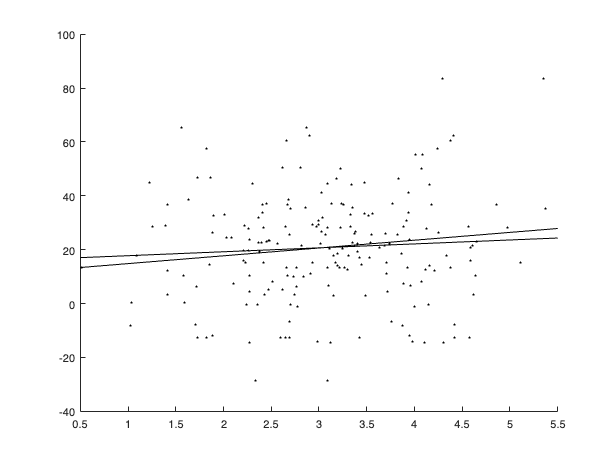



% Generate variables
x1 = 3 + randn(100, 1); x2 = 3 + randn(100, 1); x3 = x1 .* x2;
% Generate design matrix (X)
X = [x1 x2 x3 ones(size(x1))];
% Generate simulated DV (y)
y = X * [1 1 1 5]' + 20 * randn(size(x1));

figure; hold on; plot(x1, y, 'k.'); refline
plot(x2, y, 'k.'); refline

corr(X)

ans =     1.0000   -0.0869    0.6500       NaN
   -0.0869    1.0000    0.6701       NaN
    0.6500    0.6701    1.0000       NaN
       NaN       NaN       NaN       NaN


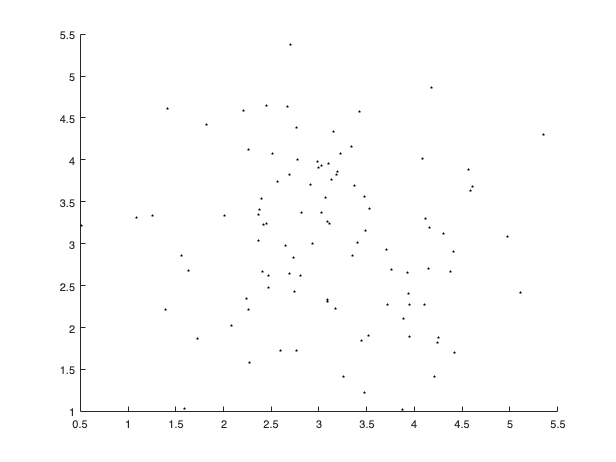

figure; hold on; plot3(x1, x2, x3, 'k.');

%figure; hold on; surf(x1, x2, x3);

vifs = getvif(X)

vifs =    12.1798   12.7666   21.9386


vifs = getvif(X(:, 1:2))

vifs =     1.0076    1.0076



[b, dev, stat] = glmfit(X(:, 1:3), y);

glm_table(stat, {'x1' 'x2' 'x1*x2'}, b);

        Name          Beta        SE         t          p         Sig 
    _____________    _______    ______    _______    ________    _____

    {'Intercept'}     60.769    23.794      2.554    0.012223    {'*'}
    {'x1'       }    -15.866    7.3046     -2.172    0.032315    {'*'}
    {'x2'       }    -14.865    7.4219    -2.0029     0.04801    {'*'}
    {'x1*x2'    }     5.8139    2.3123     2.5143    0.013589    {'*'}




% new design matrix where I center the interactions

X2 = [zscore(x1) zscore(x2) zscore(x1) .* zscore(x2) ones(size(x1))];

[b2, dev, stat2] = glmfit(X2(:, 1:3), y);

glm_table(stat2, {'x1' 'x2' 'x1*x2'}, b2);

        Name          Beta       SE         t           p           Sig  
    _____________    ______    ______    _______    __________    _______

    {'Intercept'}    21.268    1.9491     10.912    1.6599e-18    {'***'}
    {'x1'       }    1.8455    1.9608    0.94122       0.34896    {' '  }
    {'x2'       }    2.9387    1.9588     1.5003       0.13682    {' '  }
    {'x1*x2'    }    5.0906    2.0246     2.5143      0.013589    {'*'  }





t = array2table([b b2], 'RowNames', {'Intcpt' 'x1' 'x2' 'x1*x2'}, 'VariableNames', {'b_noncen' 'b_cent'});
disp(t)

              b_noncen    b_cent
              ________    ______

    Intcpt     60.769     21.268
    x1        -15.866     1.8455
    x2        -14.865     2.9387
    x1*x2      5.8139     5.0906




% this makes interaction interpretable as the crossover -- effect of x1
% depends on x2 and vice versa.

% otherwise, b3 (interaction) also

y = X * [1 0 0 5]' + 5 * randn(size(x1));

disp('No centering of predictors')
[b, dev, stat] = glmfit(X(:, 1:3), y);
glm_table(stat, {'x1' 'x2' 'x1*x2'}, b);

disp('Centering of predictors')
[b2, dev, stat2] = glmfit(X2(:, 1:3), y);
glm_table(stat2, {'x1' 'x2' 'x1*x2'}, b2);

t = array2table([b b2], 'RowNames', {'Intcpt' 'x1' 'x2' 'x1*x2'}, 'VariableNames', {'b_noncen' 'b_cent'});
disp(t)